# NAHS Examples

The following document is meant to illustrate control and estimation examples for the Nonlinear Analysis: Hybrid Systems project.

## Leader-Follower Example 1

There are 4 different leader-follower models currently developed. The first one that we considered can be exemplified by the following:


$$\begin{array}{rl}
  \dot{x}_1 = & u_1 + w_1\\
  \dot{x}_2 = & -K(x_2 - x_1 - r) + w_2 \\
  \dot{x}_3 = & -K(x_3 - x_2 - r) + w_3\\
  \dot{x}_4 = & -K(x_4 - x_1 - r) + w_4 \\
  \dot{x}_5 = & -K(x_5 - x_4 - r) + w_5 \\
  \dot{y}_1 = & u_2 + w_6\\
  \dot{y}_2 = & -K(y_2 - y_1 + r/2) + w_7 \\
  \dot{y}_3 = & -K(y_3 - y_2) + w_8 \\
  \dot{y}_4 = & -K(y_4 - y_1 - r/2) + w_9 \\
  \dot{y}_5 = & -K(y_5 - y_4) + w_{10}\\
\end{array}$$


In words, this is a model where there is a single leader agent whose location is defined by $x_1$ and $y_1$. It is followed by a rectangle of 2x2 follower agents that have desired positions dependent on the leader's (or their neighbor's) position. The rectangle will have height $r=2$ unless otherwise defined and it will have width $r \cdot s_x$ where $s_x$ is the number of follower agents in the 'row' of the follower rectangle. Parameters $s_x$ and $s_y$ are tunable here so that one can give the rectangle any number of following agents and the dynamics will be created for you automatically.

eta_w = 0.01;
eta_v = 0.01;
L2 = {ones(1,5)};

[temp1,temp2] = get_lead_follow_aff_dyn(2,2,0.1,eta_w,eta_v);
%[temp1,temp2] = get_lead_follow_aff_dyn3(2,2,0.1,'disturb_info',eta_w,eta_v);

temp2.eq_rec_design_pb('Min_M2',5,L2)

This causes a severe delay in SOLVESDP when I try to find available solvers.
To avoid this, use the options CACHESOLVERS in SDPSETTINGS.
See the FAQ for more information.
Academic license - for non-commercial use only
Optimize a model with 39920 rows, 26911 columns and 239900 nonzeros
Coefficient statistics:
  Matrix range     [3e-05, 5e+00]
  Objective range  [1e+00, 1e+00]
  Bounds range     [0e+00, 0e+00]
  RHS range        [1e-03, 9e+00]

Concurrent LP optimizer: dual simplex and barrier
Showing barrier log only...

Presolve removed 31800 rows and 10600 columns
Presolve time: 0.19s
Presolved: 8120 rows, 16311 columns, 88700 nonzeros


Solved with dual simplex
Solved in 927 iterations and 0.34 seconds
Optimal objective  5.688193321e+00


ans = struct with fields:
    yalmiptime: 2.6987
    solvertime: 0.6218
          info: 'Successfully solved (GUROBI-GUROBI)'
       problem: 0
         Q_set: {[10×50 double]}
         r_set: {[10×1 double]}
            M2: 5.6882


## Leader Follower Example 2

In this case, we are looking for the following a system that tracks a leader node which will be represented by a disturbance. Let:


$$\begin{array}{rl}
\dot{\ell}_x(t) = & w_1(t) \\
\dot{\ell}_y(t) = & w_2(t)
\end{array}$$


The leader's dynamics are like this and a cube of followers is trying to follow it according to a unique specification. I will illustrate it below with a 2x2 example:


$$\left[
\begin{array}{rl}
\dot{x}_1 \\
\dot{x}_2 \\
\dot{x}_3 \\
\dot{x}_4 \\
\dot{y}_1 \\
\dot{y}_2 \\
\dot{y}_3 \\
\dot{y}_4
\end{array}
\right]
=
\left[
\begin{array}{l}
u_{x,1} \\
u_{x,2} \\
u_{x,3} \\
u_{x,4} \\
u_{y,1} \\
u_{y,2} \\
u_{y,3} \\
u_{y,4} \\
\end{array}
\right]$$


The dynamics that we will use to reflect the tracking objective is actually based on the desired following pattern. Let's consider a new set of states, the so-called 'error states' $e_{j,i}(t) \doteq j_i(t) - j_i^{(des)}(t)$ (e.g. $e_{x,3}(t) \doteq x_3(t) - x_3^{(des)}(t)$).


$$\left[
\begin{array}{rl}
\dot{e}_{x,1} \\
\dot{e}_{x,2} \\
\dot{e}_{x,3} \\
\dot{e}_{x,4} \\
\dot{e}_{y,1} \\
\dot{e}_{y,2} \\
\dot{e}_{y,3} \\
\dot{e}_{y,4}
\end{array}
\right]
=
\left[
\begin{array}{l}
u_{x,1}(t) - w_1(t) \\
u_{x,2}(t) - u_{x,1}(t) \\
u_{x,3}(t) - w_1(t) \\
u_{x,4}(t) - u_{x,3}(t) \\
u_{y,1}(t) - w_2(t) \\
u_{y,2}(t) - u_{y,1}(t) \\
u_{y,3}(t) - w_2(t) \\
u_{y,4}(t) - u_{y,3}(t) \\
\end{array}
\right]
=
\mathbf{0} x +
\left[
	\begin{array}{cccccccc}
		1 & 0 & 0 & 0 & 0 & 0 & 0 & 0 \\
		-1 & 1 & 0 & 0 & 0 & 0 & 0 & 0 \\
		0 & 0 & 1 & 0 & 0 & 0 & 0 & 0 \\
		0 & 0 & -1 & 1 & 0 & 0 & 0 & 0 \\
		0 & 0 & 0 & 0 & 1 & 0 & 0 & 0 \\
		0 & 0 & 0 & 0 & -1 & 1 & 0 & 0 \\
		0 & 0 & 0 & 0 & 0 & 0 & 1 & 0 \\
		0 & 0 & 0 & 0 & 0 & 0 & -1 & 1 \\
	\end{array}
\right]
u
+
\left[
\begin{array}{cc}
	-1 & 0 \\
	0 & 0 \\
	-1 & 0 \\
	0 & 0 \\
	0 & -1 \\
	0 & 0 \\
	0 & -1
\end{array}
\right]
w$$


%%%%%%%%%%%%%%%
%% Constants %%
%%%%%%%%%%%%%%%

eta_w = 0.4; eta_v = 0.1;
dt = 0.1;
cube_x = 2; cube_y = 2;
[~,ad0,foll_offsets] = get_lead_follow_aff_dyn3(cube_x,cube_y,dt, ...
						'disturb_info',eta_w,eta_v);

n = size(ad0.A,1);

Pu = 5*Polyhedron('lb',-ones(1,size(ad0.B,2)),'ub',ones(1,size(ad0.B,2)));

T = 6;
L1 = {ones(1,T)};
L2 = {[1,1,1],[0,1,1],[1,0,1],[1,1,0]};

periods_in_tunnel = 3; %Number of time periods in the tunnel.

rec_tries = 3;

% results.params.ad = ad0;
% results.params.Pu = Pu;
% results.params.L1 = L1;

%%%%%%%%%%%%%%%%%
%% Create Path %%
%%%%%%%%%%%%%%%%%
l0 = [6;0];

l_x0 = repmat(l0,1,1+rec_tries*T+periods_in_tunnel*3)+ ...
		[ fliplr(linspace(-l0(1),4,1+rec_tries*T+periods_in_tunnel*3)) ; zeros(1,1+rec_tries*T+periods_in_tunnel*3)];


w = l_x0(:,2:end) - l_x0(:,1:end-1);

M2_temp = 4.8;
M_t = M2_temp;
create_filters_flag = false;

if create_filters_flag
	history.oo1 = {}; history.c1 = {};
	history.oo2 = {}; history.c2 = {};
	for rec_num = 1:rec_tries
		[history.oo1{rec_num},history.c1{rec_num}] = ad0.rec_synthesis('Equalized','prefix','Minimize M2',M2_temp,L1,'Pu',Pu);
		[history.oo2{rec_num},history.c2{rec_num}] = ad0.rec_synthesis('Free','prefix','Minimize M3',M2_temp,history.oo1{rec_num}.M2,L1,'Pu',Pu);

		%Update M2
		M_t(1+(rec_num-1)*(T-1)+1:1+rec_num*(T-1)-1) = history.oo1{rec_num}.M2*ones(T-2,1);
		M_t(1+rec_num*(T-1)) = history.oo2{rec_num}.M3;

		M2_temp = history.oo2{rec_num}.M3;
	end
 
        [history.oo3,history.c3] = ad0.rec_synthesis('Equalized','prefix','Feasible Set',1,history.oo1{rec_num}.M2,L2,'Pu',Pu);

	save('results/nahs2019/lead_foll_startup_gains.mat','history','M_t','M2_temp');
else
	load('results/nahs2019/lead_foll_startup_gains.mat')
end 


results.params.M_Target = M2_temp;
results.params.M_t = M_t;
results.params.l_x = l_x0;
results.params.w_lead = w;

%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%% Plot all of the Agents %%
%%%%%%%%%%%%%%%%%%%%%%%%%%%%

t_0 = 0;

x0 = unifrnd(-M_t(1),M_t(1),n,1);
x = x0;
for contr_num = 1:length(history.c2)
	x = [x, history.c2{contr_num}.simulate_1run( ad0 , M_t(1+contr_num*(T-1)) , 'in_sigma' , L1{1} , ...
										'in_w' , w(:,(contr_num-1)*T+1:contr_num*T) , ...
										'in_x0' , x(:,end)  )]
end

x =    -4.7127   -4.7127   -4.4141   -3.9370   -3.4562   -2.9459   -2.5958   -3.0056
   -2.8544   -2.8544   -2.7190   -2.8637   -3.0065   -3.0692   -2.9275   -2.0360
   -3.7177   -3.7177   -3.4729   -3.1053   -2.7188   -2.2978   -1.9770   -2.3412
    0.0233    0.0233    0.0245   -0.3035   -0.6482   -0.7733   -0.7063    0.0326
    0.3510    0.3510    0.3335    0.2914    0.3053   -0.0970    0.3324    0.2373
   -2.5753   -2.5753   -2.4537   -2.1462   -1.8985   -1.4467   -1.9154   -1.8488
    0.4134    0.4134    0.3910    0.3624    0.4448    0.4019    0.7160    0.2833
    2.6367    2.6367    2.5137    2.2740    1.9212    1.8621    1.4974    1.8964


x =    -4.7127   -4.7127   -4.4141   -3.9370   -3.4562   -2.9459   -2.5958   -3.0056   -3.0056   -2.7437   -2.3153   -1.8765   -1.4211   -1.8840   -1.5143
   -2.8544   -2.8544   -2.7190   -2.8637   -3.0065   -3.0692   -2.9275   -2.0360   -2.0360   -1.9000   -1.9941   -2.0987   -2.1616   -1.2663   -1.2225
   -3.7177   -3.7177   -3.4729   -3.1053   -2.7188   -2.2978   -1.9770   -2.3412   -2.3412   -2.1281   -1.7847   -1.2958   -0.9686   -1.4316   -1.1764
    0.0233    0.0233    0.0245   -0.3035   -0.6482   -0.7733   -0.7063    0.0326    0.0326    0.0287   -0.2860   -0.7462   -0.8316   -0.0471    0.0121
    0.3510    0.3510    0.3335    0.2914    0.3053   -0.0970    0.3324    0.2373    0.2373    0.2178    0.1838    0.5973    0.6521    0.1524    0.1345
   -2.5753   -2.5753   -2.4537   -2.1462   -1.8985   -1.4467   -1.9154   -1.8488   -1.8488   -1.7313   -1.4407   -1.5974   -1.6031   -1.1259   -1.1413
    0.4134    0.4134    0.3910    0.3624    0.4448    0.4019    0.7160    0.2833    0.2833

x =    -4.7127   -4.7127   -4.4141   -3.9370   -3.4562   -2.9459   -2.5958   -3.0056   -3.0056   -2.7437   -2.3153   -1.8765   -1.4211   -1.8840   -1.5143   -1.5143   -1.2942   -1.2406   -1.1636   -0.9619   -0.6519   -0.3299
   -2.8544   -2.8544   -2.7190   -2.8637   -3.0065   -3.0692   -2.9275   -2.0360   -2.0360   -1.9000   -1.9941   -2.0987   -2.1616   -1.2663   -1.2225   -1.2225   -1.1034   -0.8587   -0.6374   -0.4974   -0.4974   -0.4974
   -3.7177   -3.7177   -3.4729   -3.1053   -2.7188   -2.2978   -1.9770   -2.3412   -2.3412   -2.1281   -1.7847   -1.2958   -0.9686   -1.4316   -1.1764   -1.1764   -0.9964   -0.9556   -0.8786   -0.7313   -0.4881   -0.2448
    0.0233    0.0233    0.0245   -0.3035   -0.6482   -0.7733   -0.7063    0.0326    0.0326    0.0287   -0.2860   -0.7462   -0.8316   -0.0471    0.0121    0.0121    0.0146    0.0163   -0.0182    0.0291    0.0291    0.0291
    0.3510    0.3510    0.3335    0.2914    0.3053   -0.0970    0.3324    0.2373    0.2373    0.2178    0.1838  


for in_channel_idx = 1:periods_in_tunnel
    x = [x, history.c3.simulate_1run( ad0 , M_t(1+contr_num*(T-1)) , 'in_w' , w(:,length(history.c2)*T+(in_channel_idx-1)*3+1:length(history.c2)*T+(in_channel_idx)*3) , ...
																		'in_x0' , x(:,end)  )]
end

x =    -4.7127   -4.7127   -4.4141   -3.9370   -3.4562   -2.9459   -2.5958   -3.0056   -3.0056   -2.7437   -2.3153   -1.8765   -1.4211   -1.8840   -1.5143   -1.5143   -1.2942   -1.2406   -1.1636   -0.9619   -0.6519   -0.3299   -0.3299    0.2072   -0.2558   -0.1597
   -2.8544   -2.8544   -2.7190   -2.8637   -3.0065   -3.0692   -2.9275   -2.0360   -2.0360   -1.9000   -1.9941   -2.0987   -2.1616   -1.2663   -1.2225   -1.2225   -1.1034   -0.8587   -0.6374   -0.4974   -0.4974   -0.4974   -0.4974   -0.5880    0.1563   -0.4028
   -3.7177   -3.7177   -3.4729   -3.1053   -2.7188   -2.2978   -1.9770   -2.3412   -2.3412   -2.1281   -1.7847   -1.2958   -0.9686   -1.4316   -1.1764   -1.1764   -0.9964   -0.9556   -0.8786   -0.7313   -0.4881   -0.2448   -0.2448    0.2922   -0.1707   -0.0682
    0.0233    0.0233    0.0245   -0.3035   -0.6482   -0.7733   -0.7063    0.0326    0.0326    0.0287   -0.2860   -0.7462   -0.8316   -0.0471    0.0121    0.0121    0.0146    0.0163   -0.0182    0.0291    0.0291   

x =    -4.7127   -4.7127   -4.4141   -3.9370   -3.4562   -2.9459   -2.5958   -3.0056   -3.0056   -2.7437   -2.3153   -1.8765   -1.4211   -1.8840   -1.5143   -1.5143   -1.2942   -1.2406   -1.1636   -0.9619   -0.6519   -0.3299   -0.3299    0.2072   -0.2558   -0.1597   -0.1597    0.3774    0.0837   -0.0260
   -2.8544   -2.8544   -2.7190   -2.8637   -3.0065   -3.0692   -2.9275   -2.0360   -2.0360   -1.9000   -1.9941   -2.0987   -2.1616   -1.2663   -1.2225   -1.2225   -1.1034   -0.8587   -0.6374   -0.4974   -0.4974   -0.4974   -0.4974   -0.5880    0.1563   -0.4028   -0.4028   -0.5157   -0.6850   -0.3708
   -3.7177   -3.7177   -3.4729   -3.1053   -2.7188   -2.2978   -1.9770   -2.3412   -2.3412   -2.1281   -1.7847   -1.2958   -0.9686   -1.4316   -1.1764   -1.1764   -0.9964   -0.9556   -0.8786   -0.7313   -0.4881   -0.2448   -0.2448    0.2922   -0.1707   -0.0682   -0.0682    0.4688    0.1517    0.0421
    0.0233    0.0233    0.0245   -0.3035   -0.6482   -0.7733   -0.7063    0.0326    0.0326   

x =    -4.7127   -4.7127   -4.4141   -3.9370   -3.4562   -2.9459   -2.5958   -3.0056   -3.0056   -2.7437   -2.3153   -1.8765   -1.4211   -1.8840   -1.5143   -1.5143   -1.2942   -1.2406   -1.1636   -0.9619   -0.6519   -0.3299   -0.3299    0.2072   -0.2558   -0.1597   -0.1597    0.3774    0.0837   -0.0260   -0.0260    0.5111    0.0481    0.0421
   -2.8544   -2.8544   -2.7190   -2.8637   -3.0065   -3.0692   -2.9275   -2.0360   -2.0360   -1.9000   -1.9941   -2.0987   -2.1616   -1.2663   -1.2225   -1.2225   -1.1034   -0.8587   -0.6374   -0.4974   -0.4974   -0.4974   -0.4974   -0.5880    0.1563   -0.4028   -0.4028   -0.5157   -0.6850   -0.3708   -0.3708   -0.5026    0.1027   -0.3542
   -3.7177   -3.7177   -3.4729   -3.1053   -2.7188   -2.2978   -1.9770   -2.3412   -2.3412   -2.1281   -1.7847   -1.2958   -0.9686   -1.4316   -1.1764   -1.1764   -0.9964   -0.9556   -0.8786   -0.7313   -0.4881   -0.2448   -0.2448    0.2922   -0.1707   -0.0682   -0.0682    0.4688    0.1517    0.0421    0.0421    

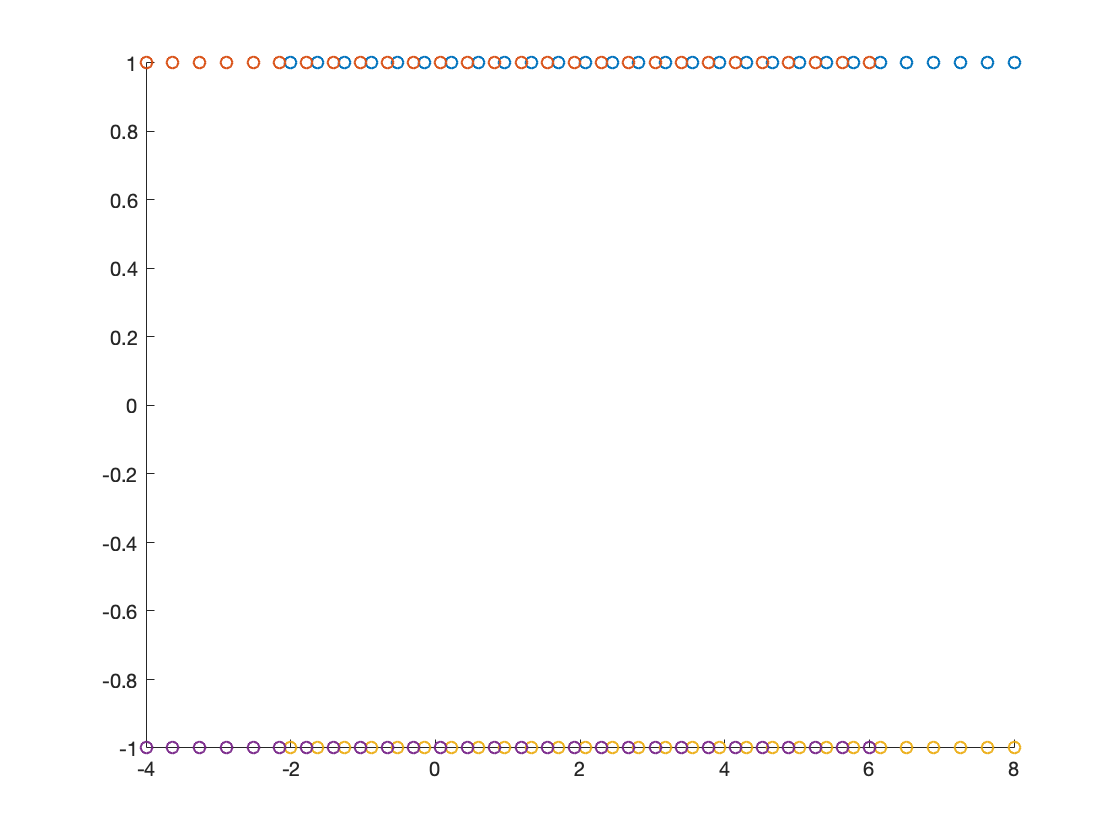


results.x_start = x;

foll_offsets2 = [foll_offsets(1,:)';foll_offsets(2,:)'];
target_pos = repmat(foll_offsets2,1,size(l_x0,2)) + [repmat(l_x0(1,:),cube_x*cube_y,1); repmat(l_x0(2,:),cube_x*cube_y,1) ];
results.targets = target_pos;

figure;
hold on;
for robot_idx = 1:cube_x*cube_y
	scatter(target_pos(robot_idx,:),target_pos(cube_x*cube_y+robot_idx,:))
end

Create a path to follow and design the obstacles.

## Comparison of Compatible Methods (State Feedback)

To compare the effect of three different, but very related methods on a simple problem we consider the Adaptive Cruise Control System from the ADHS and ACC papers.

%% Constants
acc = get_acc_aff_dyn();
n = size(acc.A,1);
m = size(acc.B,2);
p = n;		%We are assuming that state/error feedback is used here.

%Creating 2 versions of the system
acc_prime = acc;
acc_prime.C = zeros(size(acc.C));
acc_prime.C_v = zeros(size(acc.C,1));

ad_arr = [acc_prime,acc];

%Creating Disturbance Sets
M1 = 0.1;
P_x = M1*Polyhedron('lb',-1*ones(1,n),'ub',ones(1,n));
P_w = 0.2*Polyhedron('lb',-1*ones(1,size(acc.B_w,2)),'ub',ones(1,size(acc.B_w,2)));

L3 = {[1,0,1,1,1,1],[1,1,0,1,1,1],[1,1,1,0,1,1],[1,1,1,1,0,1],[1,0,0,1,1,1]};
T = length(L3{1});

[H0,S0,Cm0,J0,f_bar,B_w_big,~] = get_mpc_matrices(ad_arr,'word',L3{1}+1);

ops = sdpsettings('verbose',1);

Now, we will use the framework described in Amin et al. to try to solve this problem.


%% Create New Matrices
for sig_idx = 1:length(L3)
  		Gamma{sig_idx} = [kron(diag(L3{sig_idx}),eye(n)),zeros(n*T,n)];
    
  		%Create the J matrix for each initial estimation error value
  		temp_Jt = eye(n);
  		for t_idx = 1:T
     			temp_Jt = [temp_Jt; L3{sig_idx}(t_idx)*acc.A*temp_Jt(end-n+1:end,:) ];
  		end
  		J_tilde{sig_idx} = temp_Jt;
    
  		%Create the A matrix for the disturbance matrix within the estimation error
  		A_tilde{sig_idx} = zeros(n*(T+1),n*T);
  		nonzero_part = []; %Nonzero part of the row.
    
  		for i = 1:T
     			if i == 1
        				nonzero_part = [ eye(n) ];
        else
            %Note the integer indexing the word sigma starts from 2 as
            %defined in Skaf et. al.'s original work.
        				nonzero_part = [  (L3{sig_idx}(i))*ad_arr(L3{sig_idx}(i)+1).A*nonzero_part, eye(n) ];
     			end
        
     			%Update G Matrix
     			A_tilde{sig_idx}([i*n+1:(i+1)*n],[1:n*i]) = nonzero_part;
  		end
    
end

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%% Solve Using Shastry Group's method %%
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

%Create Variables/Sets
%Lambda = sdpvar(2*n*(T+1),size(P_x.A,1)+T*size(P_w.A,1),'full');
F = sdpvar(m*T,p*T,'full');
u0 = sdpvar(m*T,1,'full');
M2 = sdpvar(1,1,'full');

P_wT = P_w;
for pow_idx = 2:T
  		P_wT = P_wT*P_w;
end

%Create Constraints
pos_constr = []; dual_constrs = [];

big_H = [	P_x.A,zeros(size(P_x.A,1),size(P_wT.A,2));
				zeros(size(P_wT.A,1),n),P_wT.A];
for sig_idx = 1:length(L3)
  		Lambda{sig_idx} = sdpvar(2*n*(T+1),size(P_x.A,1)+T*size(P_w.A,1),'full');
  		pos_constr = pos_constr + [Lambda{sig_idx} >= 0];
    
  		[H0,S0,Cm0,J0,f_bar,B_w_big,~] = get_mpc_matrices(ad_arr,'word',L3{sig_idx}+1);
    
  		dual_constrs = dual_constrs + [Lambda{sig_idx}*big_H == [eye(n*(T+1));-eye(n*(T+1))]*[S0*F*Gamma{sig_idx}*J_tilde{sig_idx}+J0, (H0+S0*F*Gamma{sig_idx}*A_tilde{sig_idx})*B_w_big ]];
   	dual_constrs = dual_constrs + [Lambda{sig_idx}*[P_x.b;P_wT.b] <= M2*ones(2*n*(T+1),1) - [eye(n*(T+1));-eye(n*(T+1))]*(S0*u0 + H0*f_bar)];
end

l_diag_constr = [];
for bl_row_num = 1 : T-1
  		l_diag_constr = l_diag_constr + [ F([(bl_row_num-1)*m+1:bl_row_num*m],[bl_row_num*p+1:end] ) == 0 ];
end

optim0 = optimize(pos_constr+dual_constrs+l_diag_constr, M2 , ops);

results.amin.opt_info = optim0;
results.amin.F = value(F);
results.amin.u0 = value(u0);
results.amin.M2 = value(M2);

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%% Solve Using Worst Case Word Meethod %%
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

clear F u0 M2 pos_constr dual_constrs l_diag_constr

L_star = ones(1,T);
for sig_i = 1:length(L3)
  		L_star = bitand(L_star,L3{sig_i});
end

Gamma_star = [kron(diag(L_star),eye(n)),zeros(n*T,n)];

%Create the J matrix for each initial estimation error value
temp_Jt = eye(n);
for t_idx = 1:T
  		temp_Jt = [temp_Jt; L_star(t_idx)*acc.A*temp_Jt(end-n+1:end,:) ];
end
J_tilde_star = temp_Jt;

%Create the A matrix for the disturbance matrix within the estimation error
A_tilde_star = zeros(n*(T+1),n*T);
nonzero_part = []; %Nonzero part of the row.

for i = 1:T
  		if i == 1
     			nonzero_part = [ eye(n) ];
    else
        %Note the integer indexing the word sigma starts from 2 as
        %defined in Skaf et. al.'s original work.
     			nonzero_part = [  (L_star(i))*ad_arr(L_star(i)+1).A*nonzero_part, eye(n) ];
  		end
    
  		%Update G Matrix
  		A_tilde_star([i*n+1:(i+1)*n],[1:n*i]) = nonzero_part;
end

%Optimization

%Create Variables/Sets
%Lambda = sdpvar(2*n*(T+1),size(P_x.A,1)+T*size(P_w.A,1),'full');
F = sdpvar(m*T,p*T,'full');
u0 = sdpvar(m*T,1,'full');
M2 = sdpvar(1,1,'full');

P_wT = P_w;
for pow_idx = 2:T
  		P_wT = P_wT*P_w;
end

%Create Constraints
pos_constr = []; dual_constrs = [];

big_H = [	P_x.A,zeros(size(P_x.A,1),size(P_wT.A,2));
				zeros(size(P_wT.A,1),n),P_wT.A];

Lambda = sdpvar(2*n*(T+1),size(P_x.A,1)+T*size(P_w.A,1),'full');
pos_constr = pos_constr + [Lambda >= 0];

[H0,S0,Cm0,J0,f_bar,B_w_big,~] = get_mpc_matrices(ad_arr,'word',L_star+1);

dual_constrs = dual_constrs + [Lambda*big_H == [eye(n*(T+1));-eye(n*(T+1))]*[S0*F*Gamma_star*J_tilde_star+J0, (H0+S0*F*Gamma_star*A_tilde_star)*B_w_big ]];
dual_constrs = dual_constrs + [Lambda*[P_x.b;P_wT.b] <= M2*ones(2*n*(T+1),1) - [eye(n*(T+1));-eye(n*(T+1))]*(S0*u0 + H0*f_bar)];

l_diag_constr = [];
for bl_row_num = 1 : T-1
  		l_diag_constr = l_diag_constr + [ F([(bl_row_num-1)*m+1:bl_row_num*m],[bl_row_num*p+1:end] ) == 0 ];
end

optim1 = optimize(pos_constr+dual_constrs+l_diag_constr, M2 , ops);

results.worst_case.opt_info = optim1;
results.worst_case.F = value(F);
results.worst_case.u0 = value(u0);
results.worst_case.M2 = value(M2);

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%% Solve Using Prefix-Based Meethod %%
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

clear F u0 M2 pos_constr dual_constrs l_diag_constr Lambda

%Create Variables/Sets
%Lambda = sdpvar(2*n*(T+1),size(P_x.A,1)+T*size(P_w.A,1),'full');
%F = sdpvar(m*T,p*T,'full');
%u0 = sdpvar(m*T,1,'full');
M2 = sdpvar(1,1,'full');

for sig_idx = 1:length(L3)
  		%Create new variables for each pattern
  		F{sig_idx} = sdpvar(m*T,p*T,'full');
  		u0{sig_idx} = sdpvar(m*T,1,'full');
    
  		Lambda{sig_idx} = sdpvar(2*n*(T+1),size(P_x.A,1)+T*size(P_w.A,1),'full');
end

P_wT = P_w;
for pow_idx = 2:T
  		P_wT = P_wT*P_w;
end

%Create Constraints
pos_constr = []; dual_constrs = [];
shared_F_constrs = []; shared_u0_constrs = [];

big_H = [	P_x.A,zeros(size(P_x.A,1),size(P_wT.A,2));
				zeros(size(P_wT.A,1),n),P_wT.A];
for sig_idx = 1:length(L3)
    pos_constr = pos_constr + [Lambda{sig_idx} >= 0];
    
    [H0,S0,Cm0,J0,f_bar,B_w_big,~] = get_mpc_matrices(ad_arr,'word',L3{sig_idx}+1);
    
    dual_constrs = dual_constrs + [Lambda{sig_idx}*big_H == [eye(n*(T+1));-eye(n*(T+1))]*[S0*F{sig_idx}*Gamma{sig_idx}*J_tilde{sig_idx}+J0, (H0+S0*F{sig_idx}*Gamma{sig_idx}*A_tilde{sig_idx})*B_w_big ]];
    dual_constrs = dual_constrs + [Lambda{sig_idx}*[P_x.b;P_wT.b] <= M2*ones(2*n*(T+1),1) - [eye(n*(T+1));-eye(n*(T+1))]*(S0*u0{sig_idx} + H0*f_bar)];
    
    for patt_idx = sig_idx+1:length(L3)
	%Match
	p1 = L3{sig_idx};
       	p2 = L3{patt_idx};
        %Truncate one if necessary.
	if length(p1) < length(p2)
		p2 = p2(1:length(p1));
	elseif length(p1) > length(p2)
		p1 = p1(1:length(p2));
	end
	% Add xor
	p_overlap = bitxor(p1,p2);
	%Bit at which things end up being different
	ind_identical = find(p_overlap,1) - 1;
	%Awd constraints
        shared_F_constrs = shared_F_constrs +  [F{sig_idx}( [1:ind_identical*m] , [1:ind_identical*p] ) == F{patt_idx}( [1:ind_identical*m] , [1:ind_identical*p] )];
        shared_u0_constrs = shared_u0_constrs +  [u0{sig_idx}( [1:ind_identical*m] ) == u0{patt_idx}([1:ind_identical*m]) ];
    end
    
    l_diag_constr = [];
    for bl_row_num = 1 : T-1
        l_diag_constr = l_diag_constr + [ F{sig_idx}([(bl_row_num-1)*m+1:bl_row_num*m],[bl_row_num*p+1:end] ) == 0 ];
    end
end

optim2 = optimize(pos_constr+dual_constrs+l_diag_constr+shared_F_constrs+shared_u0_constrs, M2 , ops);


## Double Integrator Example

clear A B B_w;
A = [0,1,   0,0;
     0,-2, 0,0;
     0,0,   0,1;
     0,0,   0,-2];
B = [0,0;1,0;0,0;0,1];
B_w = B;

di_robot_ad = Aff_Dyn(A,B,zeros(n,1),eye(n),0.25,0.1); 

L3 = {[1,0,1,1,1,1],[1,1,0,1,1,1],[1,1,1,0,1,1]};

[opt_info1,contr1] = di_robot_ad.eq_rec_design_pb('Min_M2',1,L3)
[opt_info2,contr2] = di_robot_ad.eq_rec_design_t('Min_M2',1,L3)

%% Create Desired Path for the Robot to Track and Associated Dynamics

waypts = [[0;5],[3;2],[7;2],[10;5]];
div = 6;
x_d = [];
for waypt_idx = [1:size(waypts,2)-1]
    v_x = (waypts(1,waypt_idx+1) - waypts(1,waypt_idx))/div;
    v_y = (waypts(2,waypt_idx+1) - waypts(2,waypt_idx))/div;
    %Create x_d
    temp_x_d = [ 	linspace(waypts(1,waypt_idx),waypts(1,waypt_idx+1),div);
    		v_x*ones(1,div);
    		linspace(waypts(2,waypt_idx),waypts(2,waypt_idx+1),div);
    		v_y*ones(1,div)]; 
    
    if waypt_idx == (size(waypts,2)-1)
        x_d = [x_d,temp_x_d];
    else
        x_d = [x_d,temp_x_d(:,1:end-1)];
    end
end

ad = di_robot_ad;
ad_arr = [];
for ts_idx = 1:size(x_d,2)-1
	%Time step 0
	ad0 = ad;
	ad0.f = ad0.f + ad.A*x_d(:,ts_idx)-x_d(:,ts_idx);

	ad_arr = [ad_arr,ad0];
end

## Using Different Set Templates for Lane Keeping

The objective of this section is to test the use of different sets in our definition of Equalized Recovery. The two primary sets that we would like to test are Hybercubes (as defined by the infinity norm) and Zonotopes (as defined by a full-dimensional set of generators).

### Method 3: Sadraddini et al.

The theorem that Sadraddini's 'Linear Encodings for Polytope Containment Problems' focuses on is as follows:

**Theorem 1(Sufficient Conditions for AH-Polytope in AH-Polytope)**

Let $\mathbb{X}=\bar{x} + X\mathbb{P}_x$, $\mathbb{Y} = \bar{y} = \bar{y} + Y \mathbb{P}_y$ where $\mathbb{P}_x = \{ x \in \mathbb{R}^{n_x} \; | \; H_x x \leq h_x \}$ is a full dimensional polytope, $\mathbb{P}_y = \{ y \in \mathbb{R}^{n_y} \; | \; H_y y \leq h_y \}$, where $q_x$, $q_y$ are number of rows in $H_x$ and $H_y$, respectively. Then, we have $\mathbb{X} \subseteq \mathbb{Y}$ if:


$$\exists \Gamma \in \mathbb{R}^{n_y \times n_x}, \; \exists \beta \in \mathbb{R}^{n_y}, \; \exists \Lambda \in \mathbb{R}^{q_y \times q_x}_+$$


such that the following relations hold:


$$X = Y \Gamma, \quad \bar{y} - \bar{x} = Y \beta$$



$$\Lambda H_x = H_y \Gamma, \quad \Lambda h_x \leq h_y + H_y \beta$$


Note: The condition is necessary and sufficient in problems where $Y$ has a left inverse. Our case should be covered by this.

To make use of this, let us consider what our problem/desired polytope inclusion is: $R_{1:T} \Xi \subseteq (\mathbb{Z}_\alpha)^T$ and $R_T \Xi \subseteq \mathbb{Z}_1$. For the first inclusion, this can be depicted as follows:


$$\mathbb{X} = R_{1:T} \Xi \quad \rightarrow \quad \bar{x} = Sr + (I + SQ\bar{C})H \bar{f}, \quad X = G, \quad \mathbb{P}_x = \mathbb{P}_w^T \times \mathbb{P}_v^T \times \mathbb{P}_{\xi_0}$$



$$\mathbb{Y} = (\mathbb{Z}_\alpha)^T \quad \rightarrow \quad \bar{y} = \mathbb{1}_T \otimes c_\alpha, \quad Y = G_\alpha, \quad \mathbb{P}_y = \left \{ x \in \mathbb{R}^n \; | \; \left[ \begin{array}{c} I \\ -I \end{array}  \right] x \leq \alpha \mathbb{1}_{2n} \right \}$$


dt = 0.1;
[~,lk_ad] = get_lk_aff_dyn(dt);
	
n = size(lk_ad.A,1);
m = size(lk_ad.B,2);
p = size(lk_ad.C,1);
wd = size(lk_ad.B_w,2);
vd = size(lk_ad.C_v,2);

L = {ones(1,6)};
mu1 = 1;
mu2 = 10;
mu3 = 3;

%Create Zonotope Shapes
hypercube_bds = [0.5,0.5,0.05,0.05];
%Z1 = Zonotope(diag(hypercube_bds),zeros(n,1)); P_M1 = Polyhedron('lb',-hypercube_bds,'ub',hypercube_bds);
Z1 = Zonotope(eye(n),zeros(n,1)); P_M1 = Polyhedron('lb',-ones(1,n),'ub',ones(1,n));

Z2 = Z1;
Z2.G = 10*Z1.G;

G0 = randi(100,n);
for col_ind = 1:size(G0,2)
	G0(:,col_ind) = (1/norm(G0(:,col_ind)))*G0(:,col_ind);
end
%Z0 = Zonotope(G0,zeros(n,1));
%Z0 = Zonotope([roty(30),zeros(3,1);zeros(1,3),1],zeros(n,1));
Z0 = Zonotope(diag(hypercube_bds),zeros(n,1));

results.Z0 = Z0;
results.Z1 = Z1;
results.Z2 = Z2;

% Create Constraint Generator
cg = constr_gen();

%Optimization options
ops = sdpsettings('verbose',1);

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%% Testing Zonotope Inclusion Constraint %%
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

unit_cube = Polyhedron('lb',-ones(1,n),'ub',ones(1,n));

alpha0 = 0.001;
[dual_vars,incl_constr] = cg.create_sadraddini_AH_inclusion_constr(	Z1.c,Z1.G,unit_cube.A,unit_cube.b,...
									Z0.c,alpha0*Z0.G,unit_cube.A,unit_cube.b);

%Verify if Z1 is included in Z0. (It should not be here)
optim0 = optimize(incl_constr,[],ops);

alpha0 = 5;
[dual_vars,incl_constr] = cg.create_sadraddini_AH_inclusion_constr(	Z1.c,Z1.G,unit_cube.A,unit_cube.b,...
									Z0.c,alpha0*Z0.G,unit_cube.A,unit_cube.b);

%Verify if Z1 is included in Z0. (It should be here)
optim1 = optimize(incl_constr,[],ops);

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%% Equalized Recovery with Zonotopes %%
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

clear mu2
mu2 = sdpvar(1,1,'full');

%Select matrix
select_m = @(t,T_r) [zeros(n,t*n) eye(n) zeros(n,(T_r-t)*n) ];

obj_fcn = mu2;

max_T_i = -1;
for pattern_ind = 1 : length(L)
	T_i = length(L{pattern_ind});
	% Feedback Variables
	Q{pattern_ind} = sdpvar(m*T_i,p*T_i,'full');
	r{pattern_ind} = sdpvar(m*T_i,1,'full');

	% Dual Variables
	Pi_1{pattern_ind} = sdpvar(2*n*T_i,2*(wd+vd)*T_i+2*n,'full');
	Pi_2{pattern_ind} = sdpvar(2*n,2*(wd+vd)*T_i+2*n,'full');

	%Find the maximum T_i
	if T_i > max_T_i
		max_T_i = T_i;
	end
end
w	= sdpvar(wd*max_T_i,1,'full');

ad_prime = lk_ad;
ad_prime.C = zeros(size(lk_ad.C));

ad_arr = [ad_prime,lk_ad];

shared_Q_constrs = []; shared_r_constrs = [];
dual_equal_constrs = [];
positive_constr = [];
noise_constrs = [];
l_diag_constr = []; obj_constrs = [];

for pattern_ind = 1 : length(L)
	sigma_i = L{pattern_ind};
	T_i = length(sigma_i);
	% Creating Constraints
	% ++++++++++++++++++++

	[H0,S0,Cm0,J0,f_bar,B_w_big,C_v_big] = get_mpc_matrices(ad_arr,'word',L{pattern_ind}+1);

	positive_constr = positive_constr + [ Pi_1{pattern_ind} >= 0, Pi_2{pattern_ind} >= 0 ];

	P_wT = 1; P_vT = 1;
	for t_idx = 1:T_i
		P_wT = P_wT*ad_arr(sigma_i(t_idx)).P_w;
		P_vT = P_vT*ad_arr(sigma_i(t_idx)).P_v;
	end

	bounded_disturb_matrix = [ 	P_wT.A zeros(size(P_wT.A,1),vd*T_i+n) ;
								zeros(size(P_vT.A,1),size(P_wT.A,2)) P_vT.A zeros(size(P_vT.A,1),n) ;
								zeros(size(P_M1.A,1),(vd+wd)*T_i) P_M1.A ];

	G{pattern_ind} = [ 	(eye(n*(T_i+1))+S0*Q{pattern_ind}*Cm0)*H0*B_w_big ...
						S0*Q{pattern_ind}*C_v_big ...
						(eye(n*(T_i+1))+S0*Q{pattern_ind}*Cm0)*J0 ];

	[extra_dual_vars,z_incl_constr] = cg.create_sadraddini_AH_inclusion_constr(	S0*r{pattern_ind}+(eye(n*(T_i+1))+S0*Q{pattern_ind}*Cm0)*H0*f_bar, ...
											G{pattern_ind} , ...
											bounded_disturb_matrix,[ P_wT.b ; P_vT.b ; P_M1.b ], ...
											kron(ones(T_i+1,1),Z0.c),kron(eye(T_i+1),Z0.G), ...
											[eye((T_i+1)*n);-eye((T_i+1)*n)],mu2*ones(2*(T_i+1)*n,1));


	%Lower Diagonal Constraint
	for bl_row_num = 1 : T_i-1
		l_diag_constr = l_diag_constr + [ Q{pattern_ind}(	[(bl_row_num-1)*m+1:bl_row_num*m], ...
									[bl_row_num*p+1:end] ) == 0 ];
	end

	%Awd joint constraints for all 
	for patt_i = pattern_ind+1:length(L)
		%Match
		p1 = L{pattern_ind};
		p2 = L{patt_i};
		%Truncate one if necessary.
		if length(p1) < length(p2)
			p2 = p2(1:length(p1));
		elseif length(p1) > length(p2)
			p1 = p1(1:length(p2));
		end
		% Add xor
		p_overlap = bitxor(p1,p2);
		%Bit at which things end up being different
		ind_identical = find(p_overlap,1) - 1;
		%Awd constraints
		shared_Q_constrs = shared_Q_constrs +  [Q{pattern_ind}( [1:ind_identical*m] , [1:ind_identical*p] ) == Q{patt_i}( [1:ind_identical*m] , [1:ind_identical*p] )];
		shared_r_constrs = shared_r_constrs +  [r{pattern_ind}( [1:ind_identical*m] ) == r{patt_i}([1:ind_identical*m]) ];
	end

end

 optim3 = optimize(positive_constr+z_incl_constr+l_diag_constr+shared_Q_constrs+shared_r_constrs+obj_constrs, ...
		obj_fcn, ...
		ops);

optim3.M2 = value(mu2);

results.lk_tests.new_method.opt_out = optim3;

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%% Compare with result of the function when using hyperbox templates. %%
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

 [optim4,contr] = lk_ad.rec_synthesis( 'Equalized' , 'prefix' , 'Feasible Set' , P_M1 , optim3.M2*unit_cube , L );

results.lk_tests.hyperb_method.opt_out = optim4;
%The hyperbox problem with identical scaling is not feasible.

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%% Uze the Zonotope Method to Find a Minimal Hyperbox Solution %%
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

clear mu2
mu2 = sdpvar(1,1,'full');

%Select matrix
select_m = @(t,T_r) [zeros(n,t*n) eye(n) zeros(n,(T_r-t)*n) ];

obj_fcn = mu2;

max_T_i = -1;
for pattern_ind = 1 : length(L)
	T_i = length(L{pattern_ind});
	% Feedback Variables
	Q{pattern_ind} = sdpvar(m*T_i,p*T_i,'full');
	r{pattern_ind} = sdpvar(m*T_i,1,'full');

	% Dual Variables
	Pi_1{pattern_ind} = sdpvar(2*n*T_i,2*(wd+vd)*T_i+2*n,'full');
	Pi_2{pattern_ind} = sdpvar(2*n,2*(wd+vd)*T_i+2*n,'full');

	%Find the maximum T_i
	if T_i > max_T_i
		max_T_i = T_i;
	end
end
w	= sdpvar(wd*max_T_i,1,'full');

ad_prime = lk_ad;
ad_prime.C = zeros(size(lk_ad.C));

ad_arr = [ad_prime,lk_ad];

shared_Q_constrs = []; shared_r_constrs = [];
dual_equal_constrs = [];
positive_constr = [];
noise_constrs = [];
l_diag_constr = []; obj_constrs = [];

for pattern_ind = 1 : length(L)
	sigma_i = L{pattern_ind};
	T_i = length(sigma_i);
	% Creating Constraints
	% ++++++++++++++++++++
	[H0,S0,Cm0,J0,f_bar,B_w_big,C_v_big] = get_mpc_matrices(ad_arr,'word',L{pattern_ind}+1);

	positive_constr = positive_constr + [ Pi_1{pattern_ind} >= 0, Pi_2{pattern_ind} >= 0 ];

	P_wT = 1; P_vT = 1;
	for t_idx = 1:T_i
		P_wT = P_wT*ad_arr(sigma_i(t_idx)).P_w;
		P_vT = P_vT*ad_arr(sigma_i(t_idx)).P_v;
	end

	bounded_disturb_matrix = [ 	P_wT.A zeros(size(P_wT.A,1),vd*T_i+n) ;
								zeros(size(P_vT.A,1),size(P_wT.A,2)) P_vT.A zeros(size(P_vT.A,1),n) ;
								zeros(size(P_M1.A,1),(vd+wd)*T_i) P_M1.A ];

	G{pattern_ind} = [ 	(eye(n*(T_i+1))+S0*Q{pattern_ind}*Cm0)*H0*B_w_big ...
						S0*Q{pattern_ind}*C_v_big ...
						(eye(n*(T_i+1))+S0*Q{pattern_ind}*Cm0)*J0 ];

	[extra_dual_vars,z_incl_constr] = cg.create_sadraddini_AH_inclusion_constr(	S0*r{pattern_ind}+(eye(n*(T_i+1))+S0*Q{pattern_ind}*Cm0)*H0*f_bar, ...
											G{pattern_ind} , ...
											bounded_disturb_matrix,[ P_wT.b ; P_vT.b ; P_M1.b ], ...
											kron(ones(T_i+1,1),Z1.c),kron(eye(T_i+1),Z1.G), ...
											[eye((T_i+1)*n);-eye((T_i+1)*n)],mu2*ones(2*(T_i+1)*n,1));


	%Lower Diagonal Constraint
	for bl_row_num = 1 : T_i-1
		l_diag_constr = l_diag_constr + [ Q{pattern_ind}(	[(bl_row_num-1)*m+1:bl_row_num*m], ...
															[bl_row_num*p+1:end] ) == 0 ];
	end

	%Awd joint constraints for all 
	for patt_i = pattern_ind+1:length(L)
		%Match
		p1 = L{pattern_ind};
		p2 = L{patt_i};
		%Truncate one if necessary.
		if length(p1) < length(p2)
			p2 = p2(1:length(p1));
		elseif length(p1) > length(p2)
			p1 = p1(1:length(p2));
		end
		% Add xor
		p_overlap = bitxor(p1,p2);
		%Bit at which things end up being different
		ind_identical = find(p_overlap,1) - 1;
		%Awd constraints
		shared_Q_constrs = shared_Q_constrs +  [Q{pattern_ind}( [1:ind_identical*m] , [1:ind_identical*p] ) == Q{patt_i}( [1:ind_identical*m] , [1:ind_identical*p] )];
		shared_r_constrs = shared_r_constrs +  [r{pattern_ind}( [1:ind_identical*m] ) == r{patt_i}([1:ind_identical*m]) ];
	end
end

optim5 = optimize(positive_constr+z_incl_constr+l_diag_constr+shared_Q_constrs+shared_r_constrs+obj_constrs, ...
		obj_fcn, ...
		ops);

optim5.M2 = value(mu2);

%%%%%%%%%%%%%%%%%%%%%%%%%%%
%% Plot all 3 Polyhedron %%
%%%%%%%%%%%%%%%%%%%%%%%%%%%

Z3 = Z0;
Z3.G = optim3.M2 * Z3.G;

Z5 = Z1;
Z5.G = optim5.M2 * Z5.G;

A = [1,0,0,0;0,0,1,0];

figure;
hold on;
plot(A*Z5.to_poly())
plot(A*Z3.to_poly(),'Color','magenta')

axis equal

legend('Hyperbox M2 Set','Zonotope M2 Set')
saveas(gcf,'4d_lk_minM2.png')

disp(['Volume of Z3 is ' num2str(Z3.to_poly().volume)])
disp(['Volume of Z5 is ' num2str(Z5.to_poly().volume)])

## Using Different Set Templates for SIMPLE Lane Keeping

dt = 0.1;
lk_ad = get_simple_lk_aff_dyn(dt);
	
n = size(lk_ad.A,1);
m = size(lk_ad.B,2);
p = size(lk_ad.C,1);
wd = size(lk_ad.B_w,2);
vd = size(lk_ad.C_v,2);

L = {ones(1,6)};
mu1 = 1;
mu2 = 10;
mu3 = 3;

%Create Zonotope Shapes
Z1 = Zonotope(eye(n),zeros(n,1)); P_M1 = Polyhedron('lb',-ones(1,n),'ub',ones(1,n));

Z2 = Z1;
Z2.G = 10*Z1.G;

G0 = randi(100,n);
for col_ind = 1:size(G0,2)
	G0(:,col_ind) = (1/norm(G0(:,col_ind)))*G0(:,col_ind);
end
%Z0 = Zonotope(G0,zeros(n,1));
%Z0 = Zonotope([ [0.6;0.2],-[0.1;0.7] ],zeros(n,1));
Z0 = Zonotope([ [1;1],[1;-1] ],zeros(n,1));

results.Z0 = Z0;
results.Z1 = Z1;
results.Z2 = Z2;

% Create Constraint Generator
cg = constr_gen();

%Optimization options
ops = sdpsettings('verbose',1);

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%% Testing Zonotope Inclusion Constraint %%
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

unit_cube = Polyhedron('lb',-ones(1,n),'ub',ones(1,n));

alpha0 = 0.001;
[dual_vars,incl_constr] = cg.create_sadraddini_AH_inclusion_constr(	Z1.c,Z1.G,unit_cube.A,unit_cube.b,...
									Z0.c,alpha0*Z0.G,unit_cube.A,unit_cube.b);

%Verify if Z1 is included in Z0. (It should not be here)
optim0 = optimize(incl_constr,[],ops);

alpha0 = 5;
[dual_vars,incl_constr] = cg.create_sadraddini_AH_inclusion_constr(	Z1.c,Z1.G,unit_cube.A,unit_cube.b,...
									Z0.c,alpha0*Z0.G,unit_cube.A,unit_cube.b);

%Verify if Z1 is included in Z0. (It should be here)
optim1 = optimize(incl_constr,[],ops);

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%% Equalized Recovery with Zonotopes %%
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

clear mu2
mu2 = sdpvar(1,1,'full');

%Select matrix
select_m = @(t,T_r) [zeros(n,t*n) eye(n) zeros(n,(T_r-t)*n) ];

obj_fcn = mu2;

max_T_i = -1;
for pattern_ind = 1 : length(L)
	T_i = length(L{pattern_ind});
	% Feedback Variables
	Q{pattern_ind} = sdpvar(m*T_i,p*T_i,'full');
	r{pattern_ind} = sdpvar(m*T_i,1,'full');

	% Dual Variables
	Pi_1{pattern_ind} = sdpvar(2*n*T_i,2*(wd+vd)*T_i+2*n,'full');
	Pi_2{pattern_ind} = sdpvar(2*n,2*(wd+vd)*T_i+2*n,'full');

	%Find the maximum T_i
	if T_i > max_T_i
		max_T_i = T_i;
	end
end
w	= sdpvar(wd*max_T_i,1,'full');

ad_prime = lk_ad;
ad_prime.C = zeros(size(lk_ad.C));

ad_arr = [ad_prime,lk_ad];

shared_Q_constrs = []; shared_r_constrs = [];
dual_equal_constrs = [];
positive_constr = [];
noise_constrs = [];
l_diag_constr = []; obj_constrs = [];

for pattern_ind = 1 : length(L)
	sigma_i = L{pattern_ind};
	T_i = length(sigma_i);
	% Creating Constraints
	% ++++++++++++++++++++

	[H0,S0,Cm0,J0,f_bar,B_w_big,C_v_big] = get_mpc_matrices(ad_arr,'word',L{pattern_ind}+1);

	positive_constr = positive_constr + [ Pi_1{pattern_ind} >= 0, Pi_2{pattern_ind} >= 0 ];

	P_wT = 1; P_vT = 1;
	for t_idx = 1:T_i
		P_wT = P_wT*ad_arr(sigma_i(t_idx)).P_w;
		P_vT = P_vT*ad_arr(sigma_i(t_idx)).P_v;
	end

	bounded_disturb_matrix = [ 	P_wT.A zeros(size(P_wT.A,1),vd*T_i+n) ;
								zeros(size(P_vT.A,1),size(P_wT.A,2)) P_vT.A zeros(size(P_vT.A,1),n) ;
								zeros(size(P_M1.A,1),(vd+wd)*T_i) P_M1.A ];

	G{pattern_ind} = [ 	(eye(n*(T_i+1))+S0*Q{pattern_ind}*Cm0)*H0*B_w_big ...
						S0*Q{pattern_ind}*C_v_big ...
						(eye(n*(T_i+1))+S0*Q{pattern_ind}*Cm0)*J0 ];

	[extra_dual_vars,z_incl_constr] = cg.create_sadraddini_AH_inclusion_constr(	S0*r{pattern_ind}+(eye(n*(T_i+1))+S0*Q{pattern_ind}*Cm0)*H0*f_bar, ...
											G{pattern_ind} , ...
											bounded_disturb_matrix,[ P_wT.b ; P_vT.b ; P_M1.b ], ...
											kron(ones(T_i+1,1),Z0.c),kron(eye(T_i+1),Z0.G), ...
											[eye((T_i+1)*n);-eye((T_i+1)*n)],mu2*ones(2*(T_i+1)*n,1));


	%Lower Diagonal Constraint
	for bl_row_num = 1 : T_i-1
		l_diag_constr = l_diag_constr + [ Q{pattern_ind}(	[(bl_row_num-1)*m+1:bl_row_num*m], ...
									[bl_row_num*p+1:end] ) == 0 ];
	end

	%Awd joint constraints for all 
	for patt_i = pattern_ind+1:length(L)
		%Match
		p1 = L{pattern_ind};
		p2 = L{patt_i};
		%Truncate one if necessary.
		if length(p1) < length(p2)
			p2 = p2(1:length(p1));
		elseif length(p1) > length(p2)
			p1 = p1(1:length(p2));
		end
		% Add xor
		p_overlap = bitxor(p1,p2);
		%Bit at which things end up being different
		ind_identical = find(p_overlap,1) - 1;
		%Awd constraints
		shared_Q_constrs = shared_Q_constrs +  [Q{pattern_ind}( [1:ind_identical*m] , [1:ind_identical*p] ) == Q{patt_i}( [1:ind_identical*m] , [1:ind_identical*p] )];
		shared_r_constrs = shared_r_constrs +  [r{pattern_ind}( [1:ind_identical*m] ) == r{patt_i}([1:ind_identical*m]) ];
	end

end

 optim3 = optimize(positive_constr+z_incl_constr+l_diag_constr+shared_Q_constrs+shared_r_constrs+obj_constrs, ...
		obj_fcn, ...
		ops);

optim3.M2 = value(mu2);

results.lk_tests.new_method.opt_out = optim3;

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%% Compare with result of the function when using hyperbox templates. %%
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

 [optim4,contr] = lk_ad.rec_synthesis( 'Equalized' , 'prefix' , 'Feasible Set' , P_M1 , optim3.M2*unit_cube , L );

results.lk_tests.hyperb_method.opt_out = optim4;
%The hyperbox problem with identical scaling is not feasible.

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%% Uze the Zonotope Method to Find a Minimal Hyperbox Solution %%
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

clear mu2
mu2 = sdpvar(1,1,'full');

%Select matrix
select_m = @(t,T_r) [zeros(n,t*n) eye(n) zeros(n,(T_r-t)*n) ];

obj_fcn = mu2;

max_T_i = -1;
for pattern_ind = 1 : length(L)
	T_i = length(L{pattern_ind});
	% Feedback Variables
	Q{pattern_ind} = sdpvar(m*T_i,p*T_i,'full');
	r{pattern_ind} = sdpvar(m*T_i,1,'full');

	% Dual Variables
	Pi_1{pattern_ind} = sdpvar(2*n*T_i,2*(wd+vd)*T_i+2*n,'full');
	Pi_2{pattern_ind} = sdpvar(2*n,2*(wd+vd)*T_i+2*n,'full');

	%Find the maximum T_i
	if T_i > max_T_i
		max_T_i = T_i;
	end
end
w	= sdpvar(wd*max_T_i,1,'full');

ad_prime = lk_ad;
ad_prime.C = zeros(size(lk_ad.C));

ad_arr = [ad_prime,lk_ad];

shared_Q_constrs = []; shared_r_constrs = [];
dual_equal_constrs = [];
positive_constr = [];
noise_constrs = [];
l_diag_constr = []; obj_constrs = [];

for pattern_ind = 1 : length(L)
	sigma_i = L{pattern_ind};
	T_i = length(sigma_i);
	% Creating Constraints
	% ++++++++++++++++++++
	[H0,S0,Cm0,J0,f_bar,B_w_big,C_v_big] = get_mpc_matrices(ad_arr,'word',L{pattern_ind}+1);

	positive_constr = positive_constr + [ Pi_1{pattern_ind} >= 0, Pi_2{pattern_ind} >= 0 ];

	P_wT = 1; P_vT = 1;
	for t_idx = 1:T_i
		P_wT = P_wT*ad_arr(sigma_i(t_idx)).P_w;
		P_vT = P_vT*ad_arr(sigma_i(t_idx)).P_v;
	end

	bounded_disturb_matrix = [ 	P_wT.A zeros(size(P_wT.A,1),vd*T_i+n) ;
								zeros(size(P_vT.A,1),size(P_wT.A,2)) P_vT.A zeros(size(P_vT.A,1),n) ;
								zeros(size(P_M1.A,1),(vd+wd)*T_i) P_M1.A ];

	G{pattern_ind} = [ 	(eye(n*(T_i+1))+S0*Q{pattern_ind}*Cm0)*H0*B_w_big ...
						S0*Q{pattern_ind}*C_v_big ...
						(eye(n*(T_i+1))+S0*Q{pattern_ind}*Cm0)*J0 ];

	[extra_dual_vars,z_incl_constr] = cg.create_sadraddini_AH_inclusion_constr(	S0*r{pattern_ind}+(eye(n*(T_i+1))+S0*Q{pattern_ind}*Cm0)*H0*f_bar, ...
											G{pattern_ind} , ...
											bounded_disturb_matrix,[ P_wT.b ; P_vT.b ; P_M1.b ], ...
											kron(ones(T_i+1,1),Z1.c),kron(eye(T_i+1),Z1.G), ...
											[eye((T_i+1)*n);-eye((T_i+1)*n)],mu2*ones(2*(T_i+1)*n,1));


	%Lower Diagonal Constraint
	for bl_row_num = 1 : T_i-1
		l_diag_constr = l_diag_constr + [ Q{pattern_ind}(	[(bl_row_num-1)*m+1:bl_row_num*m], ...
															[bl_row_num*p+1:end] ) == 0 ];
	end

	%Awd joint constraints for all 
	for patt_i = pattern_ind+1:length(L)
		%Match
		p1 = L{pattern_ind};
		p2 = L{patt_i};
		%Truncate one if necessary.
		if length(p1) < length(p2)
			p2 = p2(1:length(p1));
		elseif length(p1) > length(p2)
			p1 = p1(1:length(p2));
		end
		% Add xor
		p_overlap = bitxor(p1,p2);
		%Bit at which things end up being different
		ind_identical = find(p_overlap,1) - 1;
		%Awd constraints
		shared_Q_constrs = shared_Q_constrs +  [Q{pattern_ind}( [1:ind_identical*m] , [1:ind_identical*p] ) == Q{patt_i}( [1:ind_identical*m] , [1:ind_identical*p] )];
		shared_r_constrs = shared_r_constrs +  [r{pattern_ind}( [1:ind_identical*m] ) == r{patt_i}([1:ind_identical*m]) ];
	end
end

optim5 = optimize(positive_constr+z_incl_constr+l_diag_constr+shared_Q_constrs+shared_r_constrs+obj_constrs, ...
		obj_fcn, ...
		ops);

optim5.M2 = value(mu2);

%%%%%%%%%%%%%%%%%%%%%%%%%%%
%% Plot all 3 Polyhedron %%
%%%%%%%%%%%%%%%%%%%%%%%%%%%

Z3 = Z0;
Z3.G = optim3.M2 * Z3.G;

Z5 = Z1;
Z5.G = optim5.M2 * Z5.G;

%A = [1,0,0,0;0,0,1,0];

figure;
hold on;
plot(Z5.to_poly())
plot(Z3.to_poly(),'Color','magenta')

disp(['Volume of Z3 is ' num2str(Z3.to_poly().volume)])
disp(['Volume of Z5 is ' num2str(Z5.to_poly().volume)])